# Espectrograma

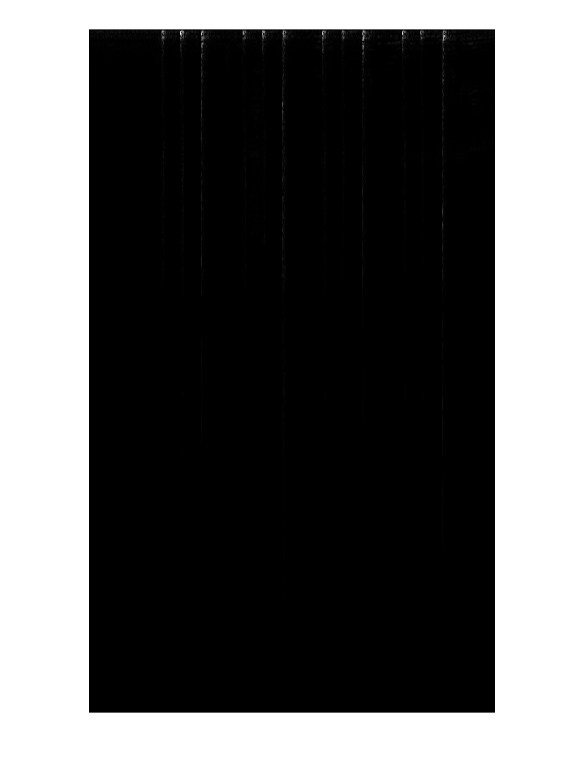

[x,fs] = audioread('Teste.m4a'); %Carrega o audio e frequencia de amostragem
%x = (x(:,1) + x(:,2))/2; %Converte para mono
x = x'; %Transpoe o vetor
std(x);  %calculo de potencia do sinal
x = x/10; %Diminui a amplitude
%sound(100*x,fs) %toca o som
N = 0.025;
X = spectrogram(x,round(N*fs));
X = X/max(abs(X(:)));
imshow(abs(X));

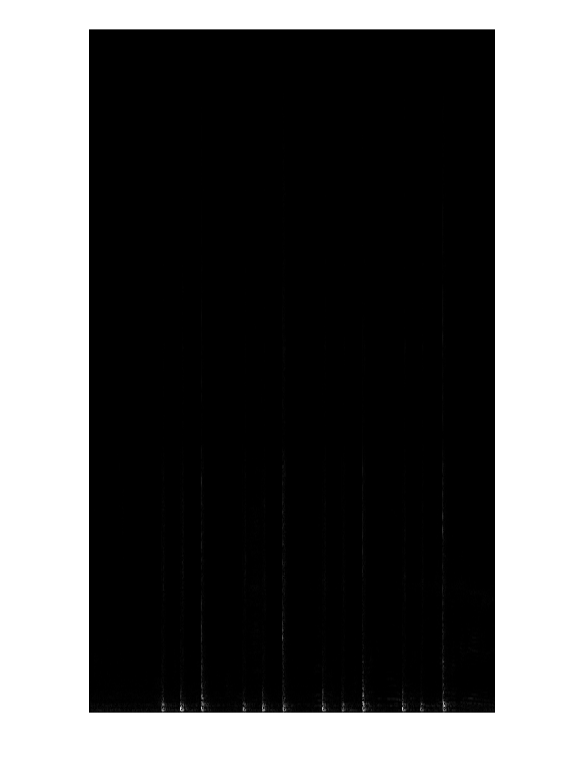

X = flipud(X);
imshow(abs(X));

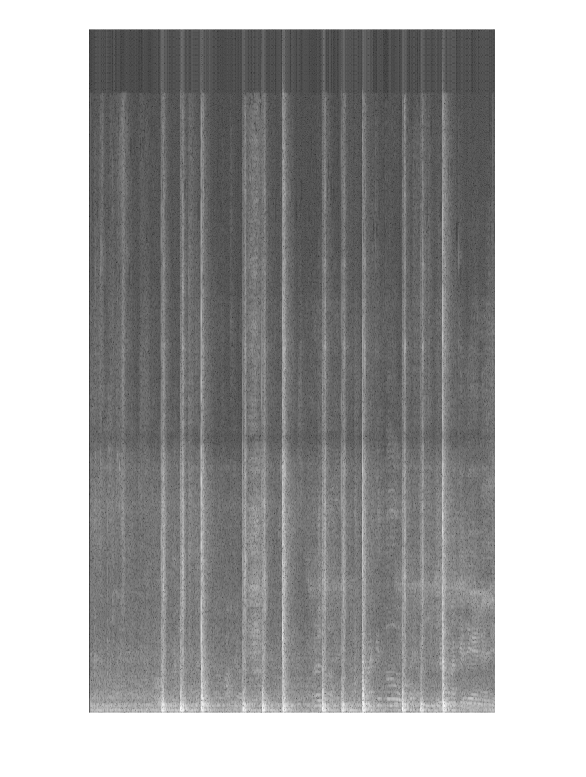

imshow(abs(X).^0.1);